# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to November 24th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix

v=[2;5;4];
R=Eaa2rotMat(65,v);

R =     0.4739   -0.4121    0.7782
    0.6687    0.7434   -0.0136
   -0.5729    0.5268    0.6279


determinant = det(R); 

**The determinant of this matrix is 1, that confirms that R is a rotation matrix.**

- Compare the transpose and the inverse of the resulting matrix

t=transpose(R);
i=inv(R);
comp=(t-i);

**When we substract the inverse of R to R transposed, the output is 0, showing that the inverse of R is equal to R transposed when we work with Rotation Matrices.**

- Using the output matrix, transform a vector parallel to the axis of rotation. 

w=v*2;
parallel_vec=R*w;

What happens?

**The transformed vector is the same as the vetor before the transform. That's because the vector is parallel to the rotation axis so it is not rotating at all.**

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the scalar product between the original vector (the unrotated vector) and the rotated one.

b=v+[0;1;0];%vector b has to be linearly independent from vector v
perpendicular_vec=cross(v,b);
perpendicular_rotated=R*perpendicular_vec;
escalar_vecs=dot(perpendicular_vec,perpendicular_rotated);
angle_result = acosd(escalar_vecs / (norm(perpendicular_vec)* norm(perpendicular_rotated)));

 What you observe? (Hint: Think about the scalar product definition)

**The angle between the 2 vectors is the same of the one in the rotation matrix, because the vectors are perpendicular to the axis of rotation and thus they get the full rotation angle.**

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100);

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

TM = zeros(1,100);
for i=1:1:100
    Uaxis = axisM(:,i);
    RotMat = Eaa2rotMat(theta(1,i)*(180/pi),Uaxis);
    TM(:,i) = RotMat(1,1) + RotMat(2,2) + RotMat(3,3);
end

R =      1     0     0
     0     1     0
     0     0     1


R =     0.9983    0.0515    0.0285
   -0.0455    0.9825   -0.1808
   -0.0373    0.1791    0.9831


R =     0.9621   -0.2629    0.0728
    0.2349    0.9342    0.2686
   -0.1386   -0.2413    0.9605


R =     0.8642    0.3571    0.3543
   -0.4265    0.8936    0.1397
   -0.2667   -0.2718    0.9246


R =     0.7452    0.5922   -0.3066
   -0.5100    0.8023    0.3101
    0.4296   -0.0748    0.8999


R =     0.6076   -0.7697   -0.1959
    0.6925    0.6342   -0.3439
    0.3889    0.0733    0.9183


R =     0.4154    0.8163    0.4013
   -0.8176    0.5285   -0.2287
   -0.3988   -0.2331    0.8869


R =     0.3119   -0.8396    0.4447
    0.9501    0.2758   -0.1455
   -0.0005    0.4679    0.8838


R =     0.1171   -0.5310    0.8392
    0.8704    0.4617    0.1707
   -0.4782    0.7105    0.5163


R =     0.3180   -0.1188   -0.9406
    0.9327    0.2174    0.2879
    0.1703   -0.9688    0.1799


R =     0.7177    0.6438    0.2654
   -0.1198   -0.2614    0.9578
    0.6860   -0.7192   -0.1104


R =    -0.2231   -0.9328   -0.2829
   -0.0031    0.2909   -0.9567
    0.9748   -0.2126   -0.0678


R =     0.2779    0.6019   -0.7487
   -0.3881   -0.6426   -0.6606
   -0.8787    0.4741    0.0550


R =    -0.0140    0.2239    0.9745
   -0.6766   -0.7197    0.1556
    0.7362   -0.6572    0.1615


R =     0.2043    0.9638   -0.1715
    0.8851   -0.1070    0.4528
    0.4181   -0.2443   -0.8749


R =    -0.5877    0.7694    0.2502
    0.7672    0.6281   -0.1297
   -0.2569    0.1158   -0.9595


R =     0.5773    0.6224   -0.5285
    0.6754   -0.7277   -0.1193
   -0.4589   -0.2881   -0.8405


R =     0.2985   -0.9533    0.0467
   -0.9521   -0.2941    0.0836
   -0.0660   -0.0695   -0.9954


R =     0.8181    0.5617    0.1232
    0.5003   -0.8009    0.3291
    0.2835   -0.2076   -0.9362


R =    -0.4490    0.6140   -0.6491
   -0.1547   -0.7689   -0.6203
   -0.8800   -0.1781    0.4403


R =     0.2244   -0.1510    0.9627
    0.6330   -0.7286   -0.2618
    0.7409    0.6681   -0.0679


R =     0.2364    0.8052    0.5439
   -0.1324   -0.5279    0.8389
    0.9626   -0.2703   -0.0182


R =    -0.4891   -0.0626    0.8700
    0.3110    0.9193    0.2410
   -0.8149    0.3884   -0.4302


R =     0.2724    0.8105   -0.5185
   -0.5644   -0.3018   -0.7684
   -0.7793    0.5020    0.3752


R =     0.3037    0.9492   -0.0825
   -0.2214    0.1545    0.9629
    0.9267   -0.2742    0.2571


R =     0.2919    0.8595   -0.4196
   -0.2058    0.4849    0.8500
    0.9340   -0.1618    0.3184


R =     0.6836   -0.5252    0.5068
   -0.2021    0.5310    0.8229
   -0.7013   -0.6650    0.2569


R =     0.4155   -0.8020    0.4290
    0.8103    0.5407    0.2260
   -0.4133    0.2537    0.8745


R =     0.8162   -0.3406   -0.4668
    0.5660    0.6339    0.5272
    0.1163   -0.6944    0.7101


R =     0.9139   -0.3041   -0.2688
    0.0829    0.7881   -0.6100
    0.3973    0.5352    0.7455


R =     0.9317   -0.3249    0.1622
    0.3630    0.8453   -0.3921
   -0.0097    0.4242    0.9055


R =     0.9407   -0.2376   -0.2422
    0.2731    0.9539    0.1247
    0.2014   -0.1835    0.9622


R =     0.9855   -0.1332   -0.1054
    0.1416    0.9869    0.0768
    0.0938   -0.0906    0.9915


R =     1.0000    0.0000   -0.0000
   -0.0000    1.0000   -0.0000
    0.0000    0.0000    1.0000


R =     0.9919   -0.0805    0.0979
    0.0659    0.9873    0.1446
   -0.1083   -0.1370    0.9846


R =     0.9569   -0.2569    0.1354
    0.2819    0.9338   -0.2203
   -0.0698    0.2489    0.9660


R =     0.9605    0.2765   -0.0311
   -0.2280    0.8462    0.4816
    0.1595   -0.4555    0.8758


R =     0.7243    0.3337    0.6034
   -0.3544    0.9308   -0.0893
   -0.5915   -0.1492    0.7924


R =     0.5917    0.4168   -0.6900
   -0.5285    0.8470    0.0583
    0.6087    0.3301    0.7214


R =     0.6234   -0.7260   -0.2904
    0.3458    0.5891   -0.7303
    0.7012    0.3549    0.6183


R =     0.3141    0.7772    0.5452
   -0.9427    0.3232    0.0823
   -0.1123   -0.5399    0.8342


R =     0.2556   -0.8836    0.3924
    0.8826    0.0476   -0.4676
    0.3945    0.4659    0.7920


R =     0.0997    0.9791    0.1771
   -0.6949   -0.0589    0.7167
    0.7121   -0.1945    0.6746


R =     0.4022    0.5202   -0.7534
   -0.7319   -0.3117   -0.6059
   -0.5500    0.7951    0.2554


R =     0.4200    0.5669   -0.7087
   -0.5093   -0.4991   -0.7011
   -0.7512    0.6554    0.0791


R =    -0.2076    0.9744    0.0862
    0.2111    0.1307   -0.9687
   -0.9552   -0.1829   -0.2328


R =    -0.7688    0.5719   -0.2862
   -0.6369   -0.7248    0.2626
   -0.0572    0.3842    0.9215


R =    -0.8352    0.5352    0.1268
   -0.0679    0.1284   -0.9894
   -0.5458   -0.8349   -0.0710


R =     0.9086    0.2857   -0.3046
    0.1857   -0.9298   -0.3179
   -0.3740    0.2323   -0.8979


R =     0.2916    0.9463    0.1394
    0.9232   -0.3166    0.2179
    0.2503    0.0652   -0.9660


R =    -0.9733   -0.0148    0.2290
   -0.1817   -0.5599   -0.8084
    0.1402   -0.8284    0.5423


R =     0.4048    0.7791   -0.4786
    0.8944   -0.4463    0.0300
   -0.1903   -0.4402   -0.8775


R =    -0.7679   -0.2508   -0.5894
    0.5783   -0.6670   -0.4697
   -0.2753   -0.7016    0.6573


R =    -0.7854    0.2673    0.5582
   -0.2061    0.7375   -0.6431
   -0.5836   -0.6202   -0.5242


R =     0.1203   -0.6721   -0.7307
    0.4167   -0.6338    0.6516
   -0.9010   -0.3829    0.2038


R =     0.2183    0.5131   -0.8301
    0.9086    0.2035    0.3647
    0.3561   -0.8338   -0.4218


R =     0.2189   -0.6232   -0.7508
   -0.6817    0.4528   -0.5746
    0.6981    0.6376   -0.3258


R =    -0.1204   -0.8282   -0.5474
    0.9575    0.0487   -0.2844
    0.2622   -0.5583    0.7871


R =     0.3132   -0.2554   -0.9147
    0.8869    0.4230    0.1856
    0.3395   -0.8694    0.3590


R =     0.4096   -0.4490   -0.7941
    0.8605    0.4793    0.1728
    0.3030   -0.7541    0.5827


R =     0.4244   -0.4907   -0.7610
    0.6052    0.7789   -0.1647
    0.6735   -0.3906    0.6275


R =     0.6765    0.3675   -0.6382
   -0.0281    0.8788    0.4763
    0.7359   -0.3042    0.6048


R =     0.7501    0.5052    0.4267
   -0.5940    0.7984    0.0990
   -0.2907   -0.3277    0.8990


R =     0.8476    0.4813   -0.2234
   -0.5041    0.8618   -0.0561
    0.1656    0.1602    0.9731


R =     0.9860    0.1036    0.1303
   -0.0538    0.9391   -0.3394
   -0.1576    0.3276    0.9316


R =     0.9822    0.0981    0.1603
   -0.0945    0.9951   -0.0300
   -0.1625    0.0143    0.9866


R =     1.0000    0.0000   -0.0000
   -0.0000    1.0000    0.0000
    0.0000   -0.0000    1.0000


R =     0.9923   -0.1229    0.0157
    0.1239    0.9820   -0.1429
    0.0022    0.1437    0.9896


R =     0.9328    0.1790    0.3129
   -0.2080    0.9762    0.0617
   -0.2944   -0.1227    0.9478


R =     0.9209    0.1719    0.3497
   -0.0182    0.9154   -0.4021
   -0.3893    0.3640    0.8462


R =     0.7483   -0.6360    0.1887
    0.6625    0.7309   -0.1638
   -0.0338    0.2476    0.9683


R =     0.6526   -0.3249   -0.6845
    0.5769    0.7987    0.1709
    0.4912   -0.5064    0.7087


R =     0.6798   -0.0708   -0.7299
    0.5802    0.6607    0.4763
    0.4486   -0.7473    0.4903


R =     0.3360   -0.8576    0.3895
    0.5238    0.5138    0.6795
   -0.7828   -0.0243    0.6218


R =     0.6751   -0.7024    0.2257
    0.3947    0.0853   -0.9149
    0.6233    0.7067    0.3348


R =     0.6348   -0.7574   -0.1529
    0.1901   -0.0388    0.9810
   -0.7490   -0.6518    0.1194


R =     0.3766   -0.6986   -0.6084
    0.5927   -0.3231    0.7378
   -0.7120   -0.6384    0.2924


R =    -0.1532   -0.2093   -0.9658
    0.9877   -0.0632   -0.1429
   -0.0311   -0.9758    0.2164


R =    -0.6547    0.4760   -0.5872
   -0.4495    0.3794    0.8087
    0.6078    0.7934   -0.0345


R =    -0.1693    0.7246   -0.6681
   -0.2329   -0.6881   -0.6872
   -0.9576    0.0393    0.2853


R =    -0.6312    0.7583   -0.1632
    0.1514   -0.0859   -0.9847
   -0.7607   -0.6462   -0.0606


R =    -0.8170   -0.0199   -0.5762
    0.4674   -0.6081   -0.6417
   -0.3376   -0.7936    0.5061


R =    -0.2129   -0.8289    0.5173
   -0.8976   -0.0433   -0.4387
    0.3860   -0.5577   -0.7348


R =    -0.9955    0.0481   -0.0820
   -0.0526    0.4403    0.8963
    0.0792    0.8966   -0.4358


R =    -0.1556   -0.6425    0.7503
   -0.2602   -0.7061   -0.6586
    0.9529   -0.2977   -0.0573


R =     0.1893    0.9458   -0.2637
    0.9226   -0.0794    0.3776
    0.3363   -0.3148   -0.8876


R =    -0.6423    0.0160   -0.7663
    0.7483    0.2295   -0.6224
    0.1659   -0.9732   -0.1594


R =    -0.2333    0.9721   -0.0242
    0.1210    0.0538    0.9912
    0.9648    0.2284   -0.1301


R =    -0.0739   -0.6266    0.7758
    0.8233   -0.4773   -0.3071
    0.5627    0.6161    0.5512


R =    -0.0836    0.3943    0.9152
    0.6236    0.7371   -0.2606
   -0.7773    0.5489   -0.3075


R =    -0.0808   -0.0065   -0.9967
    0.5039    0.8625   -0.0464
    0.8600   -0.5060   -0.0664


R =     0.0505    0.7207   -0.6914
   -0.6435    0.5529    0.5294
    0.7638    0.4181    0.4917


R =     0.2400   -0.6843   -0.6885
    0.7599    0.5738   -0.3054
    0.6041   -0.4499    0.6577


R =     0.6993   -0.7092    0.0895
    0.4054    0.4967    0.7674
   -0.5887   -0.5004    0.6349


R =     0.7628   -0.6435    0.0633
    0.4715    0.6205    0.6266
   -0.4425   -0.4481    0.7768


R =     0.8567    0.0546   -0.5129
   -0.3113    0.8476   -0.4298
    0.4112    0.5278    0.7431


R =     0.8993    0.2342   -0.3692
   -0.0927    0.9274    0.3624
    0.4273   -0.2917    0.8558


R =     0.9610    0.2128    0.1765
   -0.2509    0.9395    0.2334
   -0.1161   -0.2686    0.9562


R =     0.9899   -0.1317    0.0518
    0.1241    0.9837    0.1298
   -0.0681   -0.1221    0.9902


R =      1     0     0
     0     1     0
     0     0     1


- Make a plot of the vector that you have obtained vs the theta angle. Explain why would you expect this result.

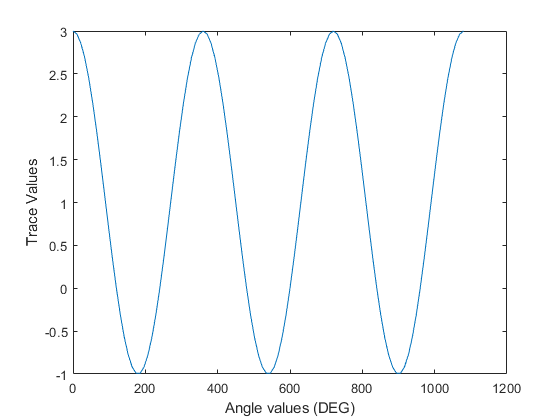

plot(theta*180/pi, TM);
ylabel("Trace Values");
xlabel("Angle values (DEG)");

               * Explanation here*

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


R = eye(3);
M_mod = (R*M')';
Cubeplot(M_mod);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

- Compare the transpose and the inverse of the resulting matrix

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.